% Specify the input audio file
inputFile ='noise_removed.wav';
[x, fs] = audioread(inputFile);

% Loop through the frames and process them as needed
numFrames = size(frames, 2)

Execution of script frames as a function is not supported:
C:\Users\Lenovo\Documents\MATLAB\DSP\Digital-Signal-Processing\project\frames.mlx

for i = 1:numFrames
    currentFrame =sprintf('frame%d.wav', i)
    [x,fs]=audioread(currentFrame)
    N=length(x);
    n=(0:N-1);
    W=0.54-0.46*cos(2*pi*n/(N-1));
    windowed=x.*W;
    y=fft(windowed,512);
    y=y(1:257)
    [coeffs,delta,deltaDelta,loc] = mfcc(y,fs);
    mfcc(y,fs)
end

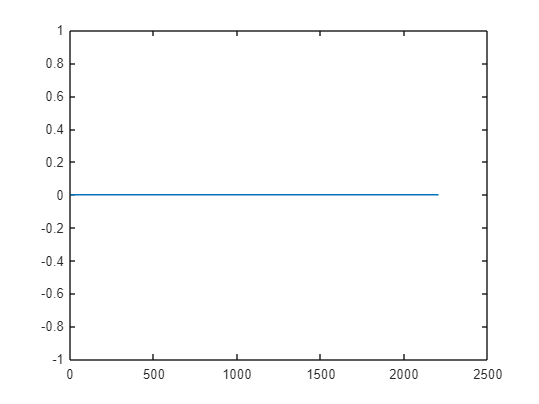

for i=1:numFrames
    currentFrame =sprintf('frame%d.wav', i);
    [x,fs]=audioread(currentFrame);
    plot(x)
end

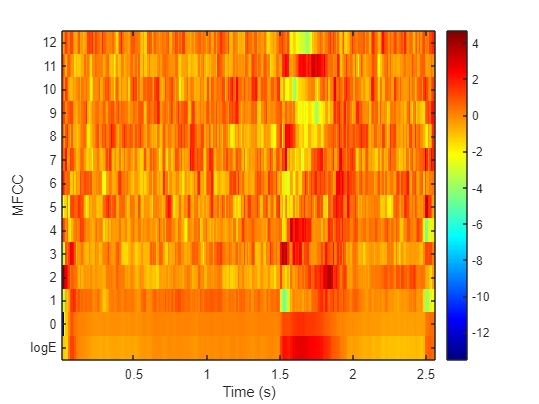

[audioIn,fs] = audioread("C:\Users\Lenovo\Documents\MATLAB\DSP\Digital-Signal-Processing\audio_files\two.wav");
[coeffs,delta,deltaDelta,loc] = mfcc(audioIn,fs);
mfcc(audioIn,fs)